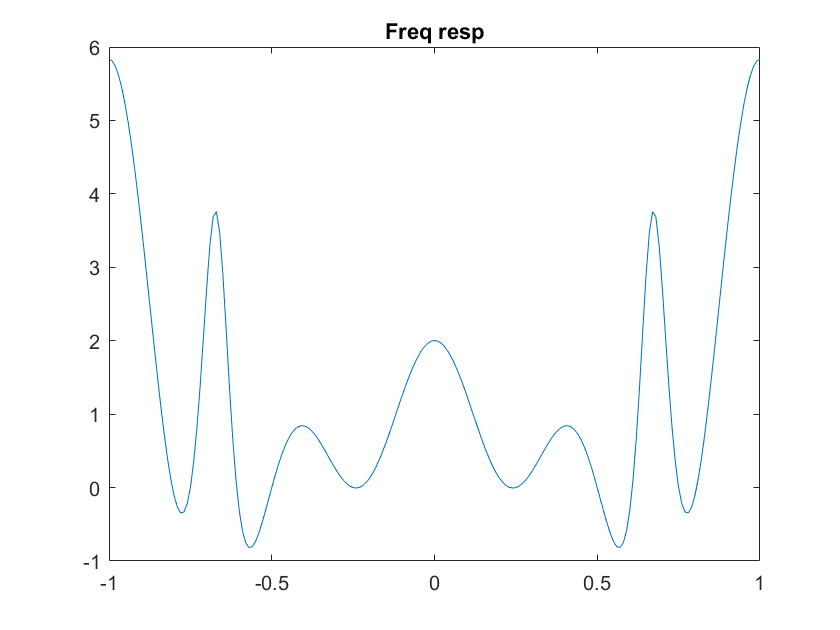

% incomplete prb 3.20
b=[1 0 1 0 1 0 1];
l=1:3;
a=(0.81).^l;
K=100;
k=-K:K;
w=k*pi/K;
H=freqres(b,a,w);

figure("Name",'Frequency response')
% dfp4(H,w)
plot(w/pi,real(H))
title('Freq resp')

% figure("Name",'Frequeeency response')
% dfp4(hv,w)
n=0:200;
% x=5+10*(-1).^n;
x=cos(pi*n)

x =      1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1


figure("Name",'Response')
subplot(3,1,1)
plot(n,x)
title('input signal')
y=H.*x

y =    5.8365 - 0.0000i  -5.8106 + 0.4402i   5.7333 - 0.8740i  -5.6057 + 1.2952i   5.4297 - 1.6976i  -5.2077 + 2.0753i   4.9431 - 2.4228i  -4.6396 + 2.7347i   4.3018 - 3.0062i  -3.9348 + 3.2331i   3.5441 - 3.4116i  -3.1360 + 3.5383i   2.7169 - 3.6108i  -2.2938 + 3.6271i   1.8743 - 3.5862i  -1.4659 + 3.4874i   1.0769 - 3.3313i  -0.7157 + 3.1191i   0.3912 - 2.8531i  -0.1129 + 2.5366i  -0.1095 - 2.1744i   0.2655 + 1.7729i  -0.3441 - 1.3409i   0.3337 + 0.8900i  -0.2226 - 0.4360i  -0.0000 - 0.0000i   0.3426 + 0.3892i  -0.8073 - 0.6937i   1.3839 + 0.8658i  -2.0409 - 0.8510i   2.7146 + 0.5984i  -3.3053 - 0.0821i   3.6891 - 0.6689i  -3.7582 + 1.5517i   3.4743 - 2.4068i  -2.8953 + 3.0772i   2.1494 - 3.4698i  -1.3756 + 3.5756i   0.6779 - 3.4459i  -0.1112 + 3.1548i  -0.3090 - 2.7720i   0.5906 + 2.3518i  -0.7525 - 1.9318i   0.8168 + 1.5358i  -0.8046 - 1.1778i   0.7349 + 0.8652i  -0.6236 - 0.6007i   0.4844 + 0.3843i  -0.3282 - 0.2142i   0.1642 + 0.0873i



yf=filter(b,a,x);
error=max(abs(real(y)-real(yf)))

error = 6.6537

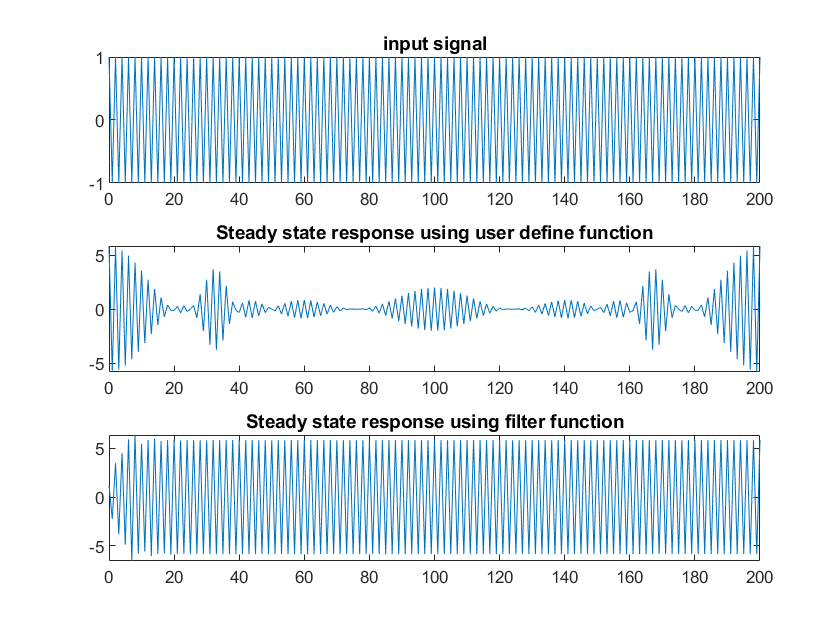

subplot(3,1,2)
plot(n,real(y))
title('Steady state response using user define function')
subplot(3,1,3)
plot(n,real(yf))
title('Steady state response using filter function')